clc
clear all
close all

%loading data
load('Received.mat')

%all_x_coor = -1200:1:-800;
all_x_coor = -1200:10:-850;
all_y_coor = 1:2:350;
%all_y_coor = 150;
energy_values = zeros(size(all_y_coor,2), size(all_x_coor,2));
i=0;
for x = all_x_coor
    i=i+1;
    j=0;
     x
    for y=all_y_coor
        j=j+1;
        sig = get_signal_at_a_point(RecSig,x, y);
        energy_sig = sig.^2;
        energy_val = sum(sum(energy_sig));
        %energy_val = max(max(sig))
        energy_values(j,i) = energy_val;
        
        
    end
    %pause(0.3)
end

x = -1200

x = -1190

x = -1180

x = -1170

x = -1160

x = -1150

x = -1140

x = -1130

x = -1120

x = -1110

x = -1100

x = -1090

x = -1080

x = -1070

x = -1060

x = -1050

x = -1040

x = -1030

x = -1020

x = -1010

x = -1000

x = -990

x = -980

x = -970

x = -960

x = -950

x = -940

x = -930

x = -920

x = -910

x = -900

x = -890

x = -880

x = -870

x = -860

x = -850

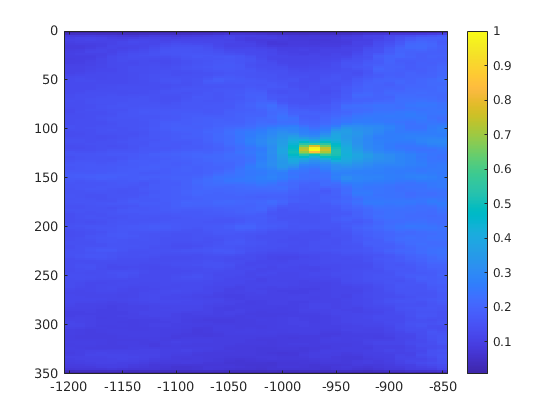

image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar

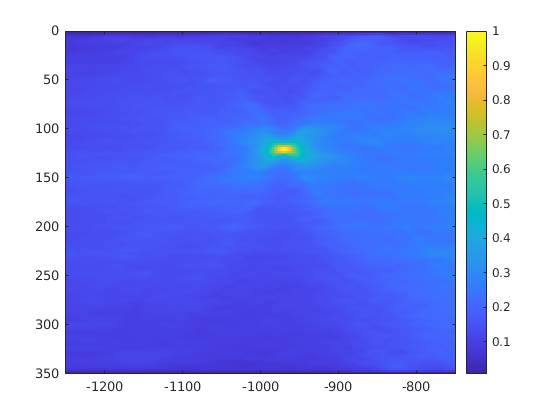

image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar


[maxValue, maxInd] = max(energy_values, [], "all", "linear")

maxValue = 5.8069e-04

maxInd = 24561

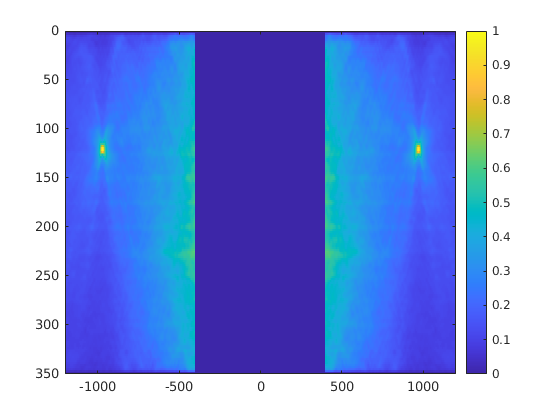

filtered_energy = energy_values;
filtered_energy(:,400:800) = zeros(175, 401);
image(all_x_coor, all_y_coor,filtered_energy/(max(max(filtered_energy))), 'CDataMapping','scaled')
colorbar

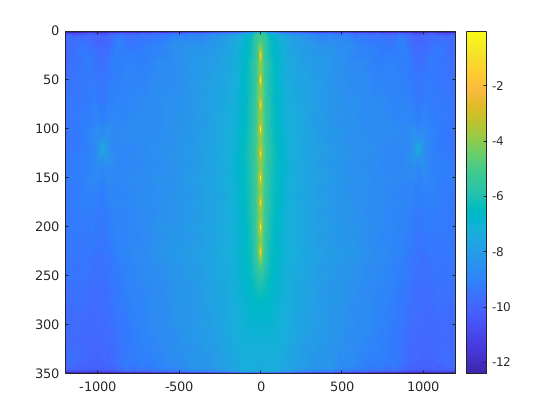

image(all_x_coor, all_y_coor,log(energy_values), 'CDataMapping','scaled')
colorbar

dummy_en = []
for i = [-500:70:-100]
sig = get_signal_at_a_point(RecSig,i, 150);
plot(t,sig)
pause(0.5)
dummy_en(end+1)=max(max(sig));
end

sig = get_signal_at_a_point(RecSig,-1000, 150);
plot(t,sig)

image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar


% plot(green(0, 1*25, 1500, 150, flip(RecSig(1,:)),t))

[Max,index] = Max3d(energy_values) 

Max = 5.8069e-04

index =     61   141


function [Max,index] =Max3d(x)
 N=size(x);
 if length(N)<2
    error(' Input 3D array');
 end
 [a,t]=max(x(:));
 Max=a;
 index1=ceil(t/(N(1)));
 %Now we find the slice that contains the Max
 Temp=x(:,index1);
 [index2]=find(Temp==max(Temp(:)));
 index=[index2;index1]';
end

function all_sig = get_signal_at_a_point(RecSig, destination_x, destination_y)
dt = 2e-4;
% t = -6.4+dt:dt:6.4;
t = dt:dt:6.4;
all_sig = 0;
for i = 1:9
    recv_signal = RecSig(i,:)';
%     disp('rcv signal')
%     plot(recv_signal)
    padding = zeros(size(t,2)-size(recv_signal,1),1);
    padded_recv_signal = cat(1,padding,recv_signal);
    
%     disp('padded rcv signal')
%     figure()
%     plot(padded_recv_signal)
%     
    reversed_padded_recv_signal = flip(padded_recv_signal);
%     disp('reveresed padded rcv signal')
%     figure()    
%     plot(t,reversed_padded_recv_signal)
    
    sig = green(0, i*25, destination_x, destination_y, reversed_padded_recv_signal,t);
    if all_sig==0
        all_sig = sig;
    else
        all_sig = all_sig+sig;
        %plot(all_sig)
        %pause(0.5)
    end
%     disp('reconstructed_signal')
%     figure()
%     plot(sig)
    
%     
end
%%%%%%

end


function R = green(xs, zs, x, z,signal, t)
h = 350; %max_height
xs = xs;
zs = zs;
x = x;
z = z;
c = 1500;

dt = 2e-4;
fs = 1/dt;

%fs = 1.0e4;

r0 = sqrt((x-xs)^2 + (z-zs)^2);
this_signal = delayseq(signal,r0/c,fs);
R = this_signal/(4*pi*r0);

for j = -8:8
    if j ==0
        continue
    end
    if rem(j,2)==0
       r = sqrt((x-xs)^2 + (z-zs+j*h)^2);
       eps = 1;
    else
       r = sqrt((x-xs)^2 + (z+zs-(j+1)*h)^2);
       eps = -1;
    end
    this_signal = delayseq(signal,r/c,fs);
    R = R+(eps/(4*pi*r) *this_signal);
end

end



